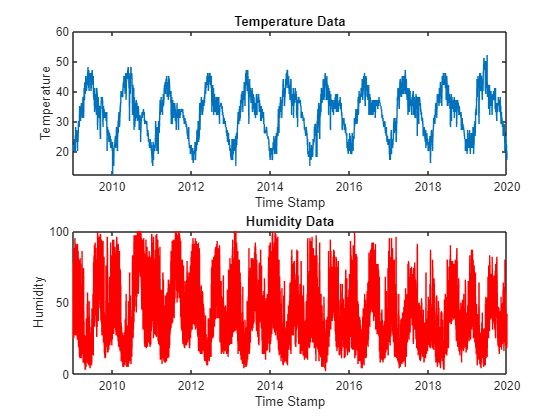

% Plotting the table

tdata = readtable('CleanedData.csv');
data = readmatrix('data.csv');
timeData = table2timetable(tdata);

figure;
subplot(2, 1, 1)
plot(timeData.date_time, timeData.maxtempC);
xlabel("Time Stamp")
ylabel("Temperature")
title("Temperature Data")

subplot(2, 1, 2)
plot(timeData.date_time, timeData.humidity, 'color', 'red');
xlabel("Time Stamp")
ylabel("Humidity")
title("Humidity Data")

timestepData = data(1,:);
WData = data(2:3,:);

numChannels = size(WData,1)

numChannels = 2

numTimesteps = numel(timestepData)

numTimesteps = 96432

% Dividing the data into 80%-20% for training and testing 
numTimestepsTrain = floor(0.8*numTimesteps)

numTimestepsTrain = 77145

dataTrain = WData(:,1:numTimestepsTrain);
dataTest = WData(:,numTimestepsTrain+1:numTimesteps);
timeDataTrain = timeData(1:numTimestepsTrain,:);
timeDataTest = timeData(numTimestepsTrain+1:numTimesteps,:);

XTrain = dataTrain(:,1:end-1);
TTrain = dataTrain(:,2:end);

XtimeDataTrain = timeDataTrain(1:end-1,:);

% Standardizing the Training data to Keep from Diverging
muX = mean(XTrain,2);
sigmaX = std(XTrain,0,2);

muT = mean(TTrain,2);
sigmaT = std(TTrain,0,2);

XTrain = (XTrain - muX) ./ sigmaX;
TTrain = (TTrain - muT) ./ sigmaT;

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:14 |         1.47 |          1.1 |          0.0010 |
|      50 |          50 |       00:04:54 |         0.35 |      6.1e-02 |          0.0010 |
|     100 |         100 |       00:09:47 |         0.26 |      3.3e-02 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


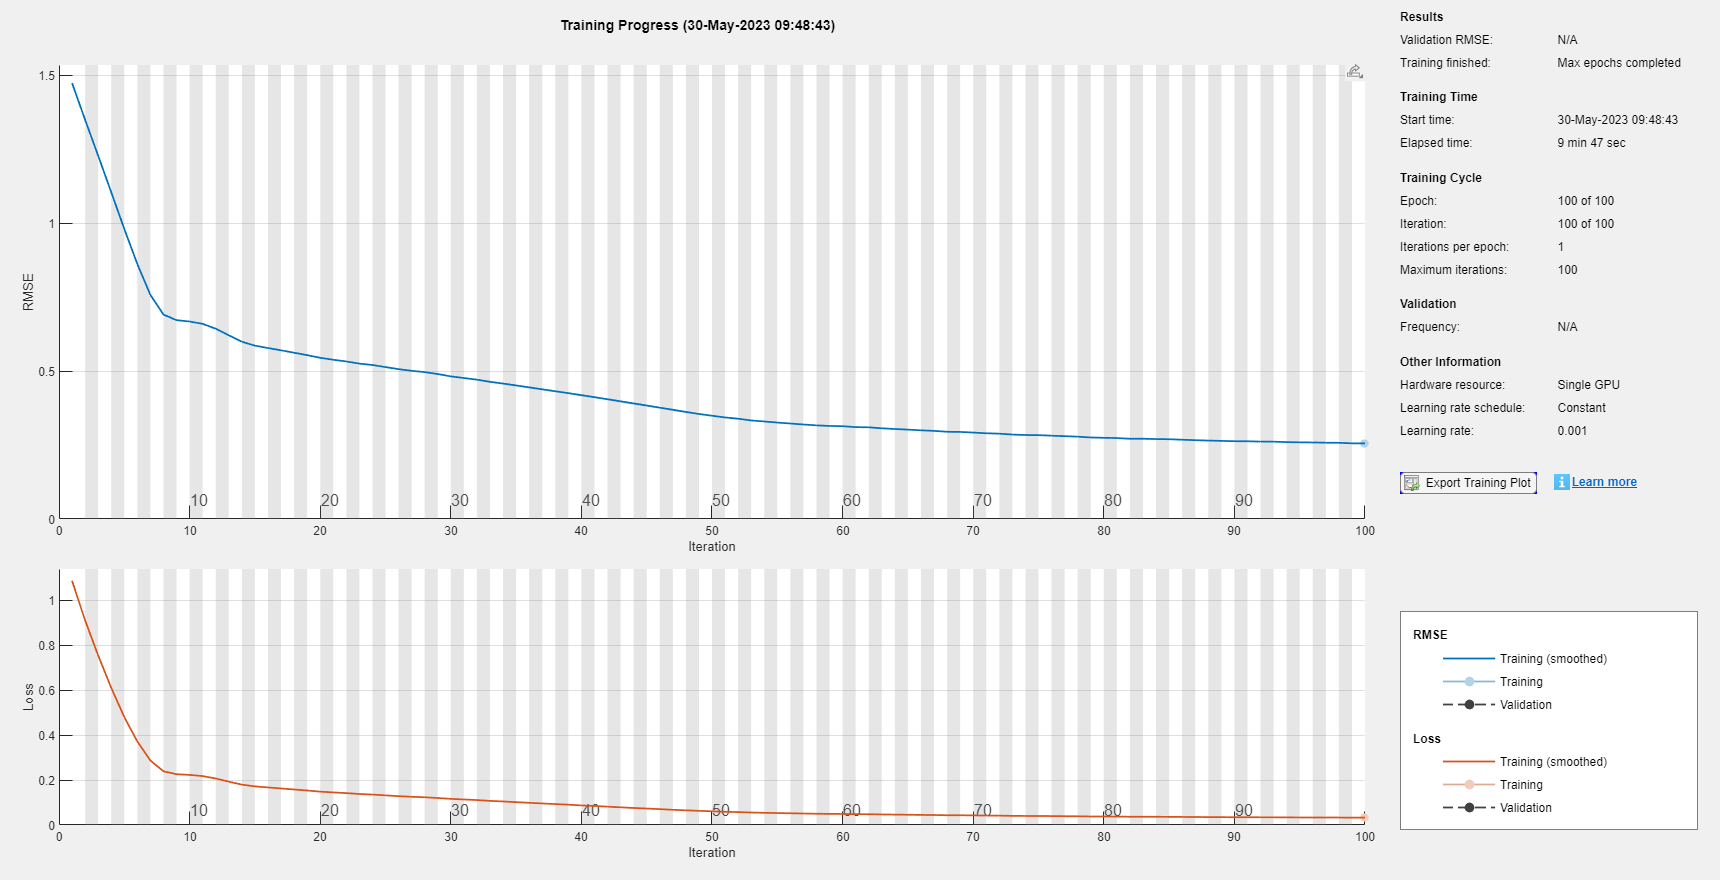

% Making layers and selecting options 
layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(128)
    dropoutLayer(0.5,"Name","drop")
    fullyConnectedLayer(numChannels)
    regressionLayer];

options = trainingOptions("adam", ...
    "ExecutionEnvironment","auto",...
    SequencePaddingDirection="left", ...
    MaxEpochs = 100, ...
    InitialLearnRate=0.001, ...
    GradientThreshold=1, ...
    Shuffle ="every-epoch", ...
    Plots="training-progress", ...
    Verbose=1);

% Training the Model
net = trainNetwork(XTrain, TTrain, layers, options);

% standardizing the Test data with the same variables as Training data
XTest = (dataTest(:,1:end-1) - muX) ./ sigmaX;
TTest = (dataTest(:,2:end) - muT) ./ sigmaT;

XtimeDataTest = timeDataTest(1:end-1,:);
TtimeDataTest = timeDataTest(2:end,:);

% Making the predictions to calculate RMSE
YTest = predict(net, XTest,SequencePaddingDirection="left");

rmse = sqrt(mean((YTest - TTest).^2, "all"))

rmse = single
0.0973

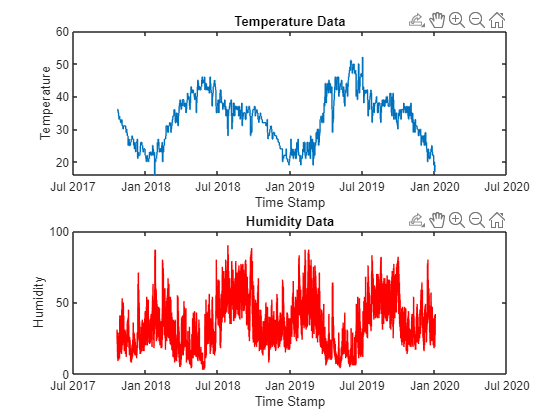

% Visualizing the Testing Data
figure;
subplot(2, 1, 1)
plot(XtimeDataTest.date_time, XtimeDataTest.maxtempC);
xlabel("Time Stamp")
ylabel("Temperature")
title("Temperature Data")

subplot(2, 1, 2)
plot(XtimeDataTest.date_time, XtimeDataTest.humidity, 'color', 'red');
xlabel("Time Stamp")
ylabel("Humidity")
title("Humidity Data")

% Resetting the network to have no impact from any previous Predictions
net = resetState(net);

% Updating the momdel on Training model
net = predictAndUpdateState(net, XTrain);

YOpenPred = [];
numTimestepsTest = size(XTest,2)

numTimestepsTest = 19286

% Making Predictions on Testing data
for i = 1:numTimestepsTest
    [net, YOpenPred(:,i)] = predictAndUpdateState(net, XTest(:,i));
end

% Unstandardizing The Predictions and Testing Data
YOpenPred = sigmaT.*YOpenPred + muT;
TUnstandardized = sigmaT.*TTest + muT;

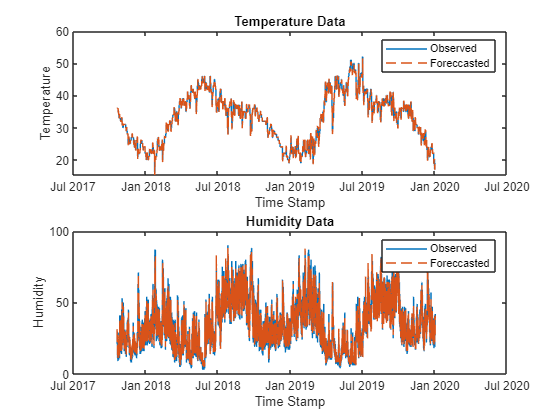

% Visualizing the Predictions
figure;

subplot(2, 1, 1)
plot(XtimeDataTest.date_time, TUnstandardized(1,:));
hold on 
plot(XtimeDataTest.date_time, YOpenPred(1,:), '--')
hold off
xlabel("Time Stamp")
ylabel("Temperature")
title("Temperature Data")
legend(["Observed" "Foreccasted"])

subplot(2, 1, 2)
plot(XtimeDataTest.date_time, TUnstandardized(2,:));
hold on 
plot(XtimeDataTest.date_time, YOpenPred(2,:), '--')
hold off
xlabel("Time Stamp")
ylabel("Humidity")
title("Humidity Data")
legend(["Observed" "Foreccasted"])